## `1. Design criteria examples:`

`Signal factors: amplitude.`

`Economic factors: financing option.`

`Social factors: usage fear.`

`Environmental factors: weight.`

`Medical safety factors: noise or vibration.`

**Review**:

Signal factor: I think amplitude should be correct.

Economic factors: financing option impacts purchase decision, thus it should be valid.

Social factor: some machines can be frightening for users, like injection. This should be valid.

Environmental factor: Like size and shape, weight is also an important factor.

Medical safety factor: vibration generated by a device should be considered a safety factor.

## `2. Specificity as environmental factor:`

`Specificity is the property of discerning the target signal from other signals in the envrionment. This is determined not only by the signal requirement, but also on other signals in the environment. That's why it's more appropriate to classify it in environmental factors.`

**Review**: the answer seems valid.

## `3. Oscilloscope`

### `a.`

`Input has 4 divisions from peak-to-peak, resulting in $``4``\times``0.5``=``2``$`` volts.`

`Output has 2 divisions from peak-to-peak, resulting in $2\times``0.1``=``0.2``$`` volts.`

`Review:``answers are correct.`

### `b.`

`Gain for this system is $V_{out}/V_{in}=0.2/2``=``0.1``$`

`Review:``answers is correct.`

### `c.`

`Frequency: the signal has period of about 6.6 divisions with time base of 0.2ms/div, resulting in $T=``0.2``\times``6.6``=``1.32``$`` ms. Frequency = $``(``1``/``1.32``)\times``1000``=``757``$`` Hz.`

`Review``: the period appeared to be 6.6 to me, whereas it's actually 6.7. I'll try to approximate better in future.`

### `d.`

`The output signal lag is about 1.6 divisions, with period of about 6.6 divisions. Lag in degrees: $1.6``/``6.6``\times``360``=``87.3``\degree``$`

`Review``: the output signal lag mark appeared to be at 1.6 to me, whereas it's actually 1.7. I'll try to approximate better in future.`

### `e.`

`The input signal is 1.8 division above arrow 1, so the offset is $1.8``\times``0.5``=``0.9``$`` volts.  `

`The output signal is 0.6 division above arrow 2, so the offset is $``0.6``\times``0.1``=``0.006``$`` volts.`

`Review``: correct.`

## `4. Mean and RMS`

syms t w
B = 1;
A = 2;

% Signal
s = B + A*sin(w*t);

% Part (a): T = 2*pi/w (one period of the signal)
T_a = 2*pi/w;

% Mean value
mean_a = (1/T_a) * int(s, t, 0, T_a);

% RMS value
rms_a = sqrt((1/T_a) * int(s^2, t, 0, T_a));

disp('4a:');

4a:


disp(['Mean: ', char(mean_a)]);

Mean: 1


disp(['RMS: ', char(rms_a)]);

RMS: 3^(1/2)



% Part (b): T = 3*pi/w (one and a half period of the signal)
T_b = 3*pi/w;

% Mean value
mean_b = (1/T_b) * int(s, t, 0, T_b);

% RMS value
rms_b = sqrt((1/T_b) * int(s^2, t, 0, T_b));

disp('4b:');

4b:


disp(['Mean: ', char(mean_b)]);

Mean: (3*pi + 4)/(3*pi)


disp(['RMS: ', char(rms_b)]);

RMS: (3*pi + 8/3)^(1/2)/pi^(1/2)


**Review: **

I calculated the values using code instead of deriving them analytically. I have corrected the answer below.

### a.


$$\begin{array}{l}
\bar{s} =\frac{1}{T}\int_0^T \left(B+A\sin (\omega t)\right)\mathrm{dt}\,\\
=\frac{1}{T}\int_0^T B\,dt+\frac{A}{T}\int_0^T \sin (\omega t)\,\mathrm{dt}\\
\,=\frac{B(T-0)}{T}+\frac{A}{T}{\left\lbrack -\frac{1}{\omega }\cos (\omega t)\right\rbrack }_0^T \\
=\frac{1}{T}\int_0^T \left(B+A\sin (\omega t)\right)\,\mathrm{dt}\\
=\frac{1}{T}\int_0^T B\,dt+\frac{A}{T}\int_0^T \sin (\omega t)\,\mathrm{dt}\\
=B+\frac{A}{T}\left(-\frac{1}{\omega }\right)\left\lbrack \cos (\omega T)-\cos (0)\right\rbrack \\
=B-\frac{A}{T\omega }\left\lbrack \cos (\omega T)-1\right\rbrack \,\\
\textrm{With}\;T=\frac{2\pi }{\omega }\,\\
B-\frac{A}{2\pi }\left\lbrack \cos (2\pi )-1\right\rbrack \,B+A(1-1)=B
\end{array}$$


For RMS value,


$$\begin{array}{l}
\textrm{Given}\;\bar{s} =B\textrm{,}\;s(t)-\bar{s} \\
=B+A\sin (\omega t)-B\\
=A\sin (\omega t)\,\\
={\left(\frac{\omega }{2\pi }\int_0^{\frac{2\pi }{\omega }} \left(A^2 \sin^2 (\omega t)\right)\mathrm{dt}\right)}^{\frac{1}{2}} \,\\
={\left(\frac{A^2 \omega }{2\pi }\int_0^{\frac{2\pi }{\omega }} \left(\frac{t}{2}-\frac{1}{4\omega }sin(2\omega t)\right)\mathrm{dt}\right)}^{\frac{1}{2}} \,\\
={\left(\frac{A^2 \omega }{4\pi }\left(\frac{2\pi }{\omega }-{\left\lbrack \frac{\sin (2\omega t)}{2\omega }\right\rbrack }_0^{\frac{2\pi }{\omega }} \right)\right)}^{\frac{1}{2}} \,\\
={\left(\frac{A^2 \omega }{4\pi }\left(\frac{2\pi }{\omega }-0\right)\right)}^{\frac{1}{2}} \,\\
={{\left(\frac{A^2 }{2}\right)}^{\frac{1}{2}} }^{\prime } \\
=\frac{A^2 }{\sqrt{2}}
\end{array}$$


### b.


$$\begin{array}{l}
T=\frac{3\pi }{\omega }\\
=B-\frac{A}{3\pi }\left\lbrack \cos (3\pi )-1\right\rbrack \\
=B-\frac{A}{3\pi }\left\lbrack -1-1\right\rbrack \\
=B-\frac{2A}{3\pi }
\end{array}$$


## 5

disp('5:');

5:



% Transfer function
syms K tau1 w
H = (K * tau1 * 1i*w) / (tau1 * 1i*w + 1);

% Magnitude
magnitude = abs(H);

% Phase
phase = angle(H);

disp(['Magnitude: ', char(magnitude)]);

Magnitude: abs(K*tau1*w)/abs(tau1*w*1i + 1)


disp(['Phase (radians): ', char(phase)]);

Phase (radians): angle((K*tau1*w*1i)/(tau1*w*1i + 1))


**Review: **

I calculated the values using code instead of deriving them analytically. I have corrected the answer below.

`For a complex number, `$a+jb$

`Magnitude `$|a+jb|=\sqrt{a^2 +b^2 }$


$$\begin{array}{l}
\frac{V_{\textrm{out}} }{V_{\textrm{in}} }=K\frac{\tau_1 j\omega }{\tau_1 j\omega +1}\,|K\tau_1 j\omega |\\
=|K|\tau_1 j\omega \,\tau_1 j\omega +1\\
=\sqrt{1+(\tau_1 \omega )^2 }
\end{array}$$


`Magnitude `$|K|\frac{\tau_1 j\omega }{\sqrt{1+(\tau_1 \omega )^2 }}$

`Phase shift `$\angle K\frac{\tau_1 j\omega }{\tau_1 j\omega +1}=\angle K+\angle \tau_1 j\omega -\angle (\tau_1 j\omega +1)$

`For a complex number, `$a+jb$

`Phase `$\angle (a+jb)=\arctan (\frac{b}{a})$


$$\begin{array}{l}
\angle K\frac{\tau_1 j\omega }{\tau_1 j\omega +1}=\arctan \frac{0}{K}+\angle \arctan \frac{\tau_1 \omega }{0}-\angle \arctan \frac{\tau_1 \omega }{1}\,\\
=0\degree +90\degree -\angle \arctan (\tau_1 \omega )
\end{array}$$


## 6 Bode Plot

disp('6:');

6:


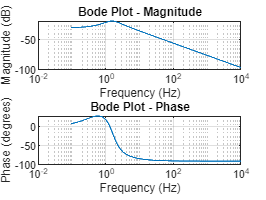

% Transfer function
num = [1 3]; % Numerator coefficients (s + 3)
den = [1 10 100]; % Denominator coefficients (s^2 + 10s + 100)

% Frequency range
f = logspace(-1, 4, 500); % 0.1 Hz to 10,000 Hz
w = 2*pi*f;

% Evaluate transfer function
H = freqs(num, den, w);

% Magnitude and phase
magnitude = abs(H);
phase = angle(H) * (180/pi); % Convert to degrees

% Plot Bode plot
figure;
subplot(2, 1, 1);
semilogx(f, 20*log10(magnitude)); % Magnitude in dB
grid on;
title('Bode Plot - Magnitude');
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');

subplot(2, 1, 2);
semilogx(f, phase); % Phase in degrees
grid on;
title('Bode Plot - Phase');
xlabel('Frequency (Hz)');
ylabel('Phase (degrees)');

Review:

Analytical solution:


$$T(s)=\frac{V_{out} }{V_{in} }=\frac{s+3}{s^2 +10s+100}$$


`Taking `$s=j\omega$


$$\begin{array}{l}
T(j\omega )=\frac{V_{out} }{V_{in} }=\frac{j\omega +3}{(j\omega )^2 +10(j\omega )+100}\\
=\frac{j\omega +3}{100-\omega^2 +10(j\omega )}
\end{array}$$


`Magnitude `$=|T(j\omega )|=\frac{|j\omega +3|}{|100-\omega^2 +10(j\omega )|}\;\,=\frac{\sqrt{9+\omega^2 }}{\sqrt{(100-\omega^2 )^2 +100\omega^2 }}$

`Phase shift `$\angle \frac{j\omega +3}{100-\omega^2 +10(j\omega )}=\arctan (\frac{\omega }{3})-\arctan (\frac{10\omega }{100-\omega^2 })$

The plots seem to be correct.

c. 3

d. 2

e. 2

f. 3

g. 2

h. 3

i. 2

j. 1

k. 2

l - m. 1

n. 3

o. 2

p. 1

q. 2

r. 4

s. 3

t. 1

u. 3